# F1_Strain_Overview.m

**Goal**: Demonstrate simulation of probiotic dosing for a 'null' probiotic strain and a 'traditional' probiotic strain Figure 1: Time series plot of composition before, during and after probiotic Figure 2: Bar chart of the response type evaluated at different time points

**Requirements**: 

MATLAB Toolboxes: Parallel Computing, Bioinformatics, Symbolic Math

Custom Scripts: Add the `probiotic_code/` folder to your path

Model inputs as defined in `define_Common_Simulation_Inputs `(*Defines virtual patient population, simulation inputs)*

*Functions:*` simulate_CST_probiotic_object.m, plot_ResponseFrequenciesByTimepoint.m, plot_ResponseFrequenciesByTimepoint.m`

## 1. Load Model Defaults

clear; clc;
ws_name = 'input_files/SSConfig-Analysis-HMP-Virtual-Population.mat';
simulationType = "base";
[POPinfo,PROBinfo,~,SIMinfo] = define_Common_Simulation_Inputs(ws_name,simulationType);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


`POPinfo`: struct that defines virtual patient population

- `virtualPatientParameter`s: # patients x 20 parameter matrix generated by LHS

- `virtualPatientComposition`: 1 x # patients cell of analytically predicted steady-state absolute abundances of nAB, Li, oLB (predicted without considering probiotic in community)

`PROBinfo`: struct that defines probiotic parameters

- dose: absolute abundance of probiotic when dosed into the base community (selected from relative abundance data observed in Dausset et al. 2018)

- numberDoses: total number of doses given

- doseFrequency: time separation (days) between each dose

`SIMinfo`: struct that defines simulation inputs

- `startProbiotic`: time point after simulation begins to start probiotic therapy

- `stopSimulation`: time point to end simulation relative to the last day of probiotic treatment

- ` initialComposition`: scaling factor to "displace" from the predicted composition (POPinfo.virtualPatientComposition). For example, 0.01 is a 1% decrease in abundance and 0.05 is a 0.5% increase from the predicted abundance

- `alteredParamIndex`: indexes of probiotic-related parameters relative to the full parameter list

- `paramAlteration`: new value for probiotic parameters (a 1 x length alteredParamIndex array of values)

- `paramAlterationType`: 'None' (use LHS probiotic parameter, ignore paramAlteration values), 'fold addition' (scale LHS probiotic parameter (LP) + paramAlteration * LP,  'absolute' (set to exact value in paramAlteration)

- `ODEoptions`: "options" input for ode solvers

- `ODEsolver:` ODE solver function handle (e.g., @ode45, @ode15s)

## 2. Run Null Probiotic Strain

SIMinfo.paramAlteration = [0.5 0 0 0 0 0 0 -0.0220]; % null probiotic (average values) 

Elapsed time is 35.238245 seconds.



tic
[select_outcomes,nonBVflag,tall,yall,warnall,...
    dose_lbls] = simulate_CST_probiotic_object(POPinfo,PROBinfo,SIMinfo);
toc

% save results
output_fdr = 'result_workspaces/';
if ~isfolder(output_fdr)
    mkdir(output_fdr)
end
fnm = strcat(output_fdr,'F1_Null_Strain.mat');
save(fnm,"select_outcomes","nonBVflag","tall","yall","warnall","dose_lbls",...
    "POPinfo","PROBinfo","SIMinfo")

Outputs saved include:

- `select_outcomes`: 3D array [# subjects x # evaluations points x # model speices + 1]. Default number of evaluation points is 8 (time points where abundance measurement is collected, the last dimension is the time point and the species abundance.

- `nonBVflag`: logica that indicates if the run is not nAB dominant when the probiotic is added

- `tall`: cell array collecting each simulations' time steps

- `yall`: cell array collecting each simulations' abundance at each time step

- `warnall`: # subjects array collecting warnings generated during numerical evaluation of the ODE

- `dose_lbls`: time points where the probiotic was given

## 3. Run Traditional Strain

SIMinfo.paramAlteration = [0.5 0 0 0 -0.012 0 0 -0.0220]; % null + strong inhibition of nAB 

tic

> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

[select_outcomes,nonBVflag,tall,yall,warnall,...

Elapsed time is 19.558268 seconds.


    dose_lbls] = simulate_CST_probiotic_object(POPinfo,PROBinfo,SIMinfo);
toc

fnm = strcat(output_fdr,'F1_Traditional_Strain.mat');
save(fnm,"select_outcomes","nonBVflag","tall","yall","warnall","dose_lbls",...
    "POPinfo","PROBinfo","SIMinfo")

## 4. Run Non-Traditional Strain

SIMinfo.paramAlteration = [0.5 0.012 0 0 0 0 0 -0.0220]; % null + strong inhibition of P 

tic
[select_outcomes,nonBVflag,tall,yall,warnall,...
    dose_lbls] = simulate_CST_probiotic_object(POPinfo,PROBinfo,SIMinfo);

> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


toc

Elapsed time is 15.154205 seconds.



fnm = strcat(output_fdr,'F1_NonTraditional_Strain.mat');
save(fnm,"select_outcomes","nonBVflag","tall","yall","warnall","dose_lbls",...
    "POPinfo","PROBinfo","SIMinfo")

## 5. Plot Results

The plotted results detail how the different strains perform across the 2000 subject virtual population.

The null strain has a failure rate (percent nAB dominant after therapy) of 46.5% whereas the traditionall strain has a failure rate of ~29%. 

Plots of the abundance-time trajectory were segmented by response type 12mo from therapy cessation. For the null probiotic, responses labeled Li or oLB dominant (classifed by a nearest centoid classifier rather than a % of nAB, which is why nAB is stilll at higher levels than Li/oLB) had nearly equall parts nAB/*Lactobacilus *spp. post-treatment. For the traditiona probiotic, the trend was different, where we see endogenous *Lactobacillus *spp. abundance slowly increase over time and after the probiotic strain peaks in abundance. Lines on the plot indicate the mean and 95% confidance intervals for each species.

Lastly, there is a plot for a "non-traditional" strain. This simulation was run because of the observed importance of the nAB->P interaction term in previous analyses. Here, I wanted to check that the value was not too strong (e.g., there was not 100% efficacy of the probiotic). This result helps guide my selection of parameter values for the 1D sensitivity analysis, which I now know must encompass positive values less than 0.12 to understand the sensitivity of this parameter.

NOTE: xline error occurs in earlier MATLAB versions (MATLAB 2020a and earlier)

output_fdr = 'result_workspaces/F1/'; % update as needed for location of your output files
ws_names = {'F1_Null_Strain.mat', 'F1_Traditional_Strain.mat','F1_NonTraditional_Strain.mat'};
[~,SSnms,sp_cols,time_names] = get_naming_terms(); % loads naming terms, default colors

null = load(strcat(output_fdr,ws_names{1})); % null strain results
trad = load(strcat(output_fdr,ws_names{2})); % traditional strain results
ntrad = load(strcat(output_fdr,ws_names{3})); % non-traditional strain results

Time points that can be selected in `time_id` or `select_timpoints` correspond to the names in the `time_names` variable.

- Mid-therapy

- Therapy cessation

- 1wk post

- 2wk post

- 1mo post

- 3mo post

- 6mo post

- 12mo post

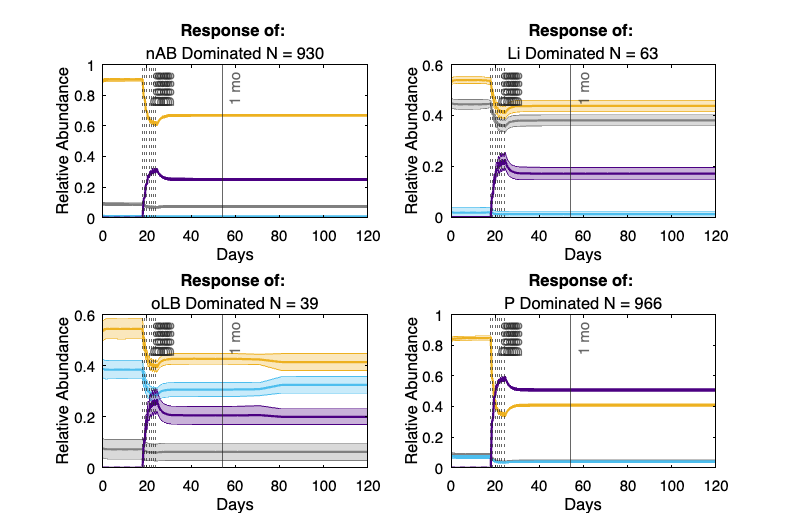

f1a(1) = figure;
time_id = 8; % 12 mo
for resp_id = 1:4 % four response types
    subplot(2,2,resp_id)
    plot_ProbioticTrajectoryByResponse(resp_id,null.select_outcomes,null.warnall,null.tall,null.yall,time_id,null.dose_lbls,SSnms,sp_cols)
end
set(f1a(1),'units','pixels','position',[1 1 600 400])

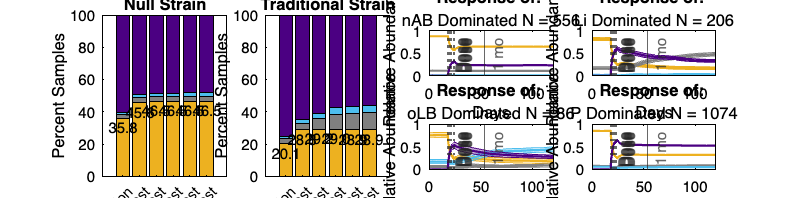


f1(1) = figure;
selected_timepoints = [2 3 5:8]; % time points evaluated (0mo - 12mo post)
subplot(2,4,[1 5])
plot_ResponseFrequenciesByTimepoint(selected_timepoints,null.select_outcomes,null.warnall,SSnms,time_names,sp_cols)
title(strrep(extractBetween(ws_names{1},'1_','.mat'),"_", " "))
subplot(2,4,[2 6])
plot_ResponseFrequenciesByTimepoint(selected_timepoints,trad.select_outcomes,trad.warnall,SSnms,time_names,sp_cols)
title(strrep(extractBetween(ws_names{2},'1_','.mat'),"_", " "))
idx = [3 4 7 8];
for resp_id = 1:4
    subplot(2,4,idx(resp_id))
    plot_ProbioticTrajectoryByResponse(resp_id,trad.select_outcomes,trad.warnall,trad.tall,trad.yall,time_id,trad.dose_lbls,SSnms,sp_cols)
end
set(f1(1),'units','pixels','position',[1 1 1600 400])
hLeg=findobj(f1(1),'type','legend'); % removes legend
set(hLeg,'visible','off')

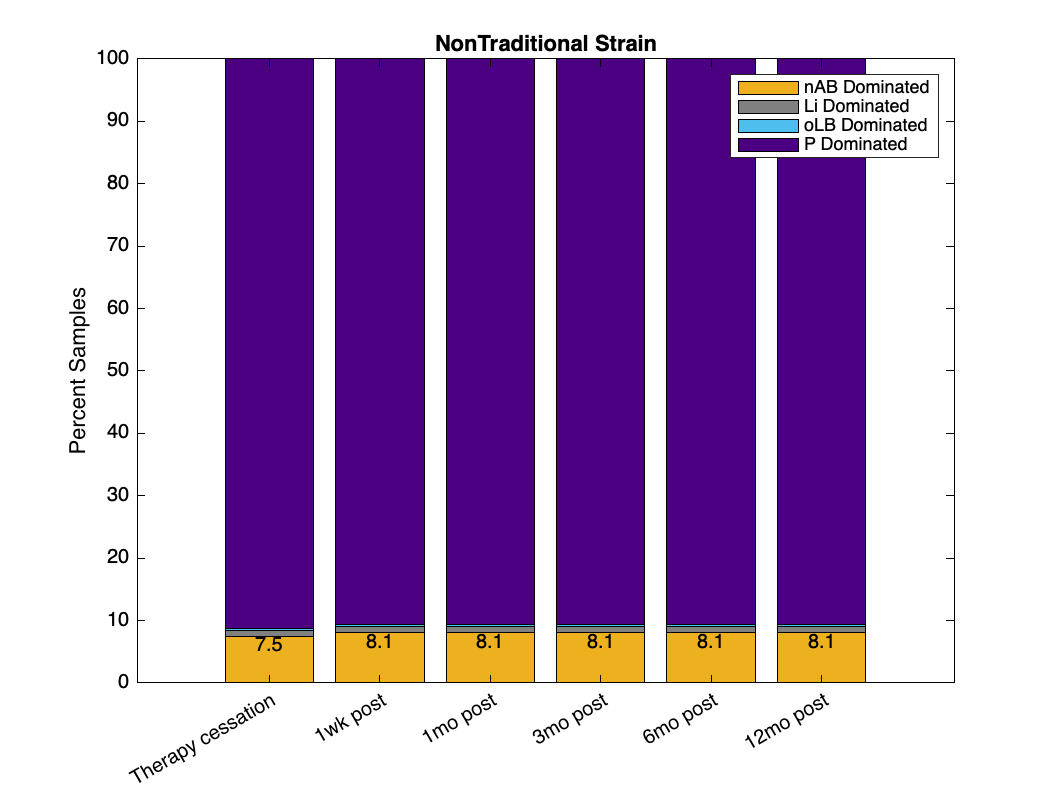


f1a(2) = figure;
plot_ResponseFrequenciesByTimepoint(selected_timepoints,ntrad.select_outcomes,ntrad.warnall,SSnms,time_names,sp_cols)
title(strrep(extractBetween(ws_names{3},'1_','.mat'),"_", " "))